clear
addpath("frffit"); addpath('Assignment 2')


a) transfer function

m = 1; %[kg]
wc = 10 %[Hz} crossover frequency

wc =     10



H = tf(1,[m 0 0])

H =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties




P = abs(m*wc^2/(1 + i))

P =    7.0711e+01


D = P/wc

D =    7.0711e+00


C = tf([D P],1)

C =
 
  7.071 s + 70.71
 
Continuous-time transfer function.
Model Properties


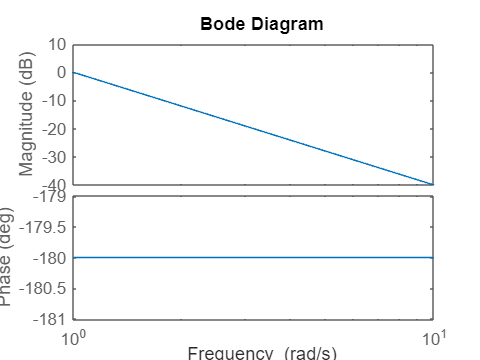

bode(H)

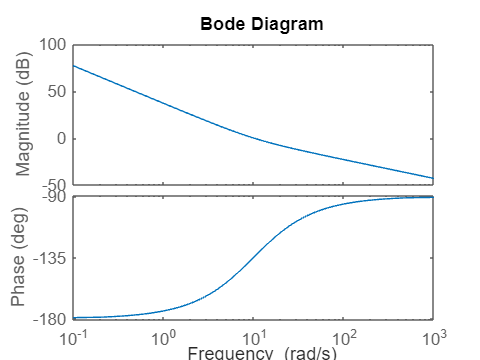

bode(H*C)

c) running simulation

stepsize = 0.001; %[s]
t_end = 120; %[s]
out = sim("two")

out =   Simulink.SimulationOutput:

                      d: [1x1 timeseries] 
                   tout: [120001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


u = out.u

  timeseries

  Common Properties:
            Name: ''
            Time: [120001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [120001x1 double]
        DataInfo: 

d = out.d

  timeseries

  Common Properties:
            Name: ''
            Time: [120001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [120001x1 double]
        DataInfo: 

fs = 1/stepsize

fs =         1000


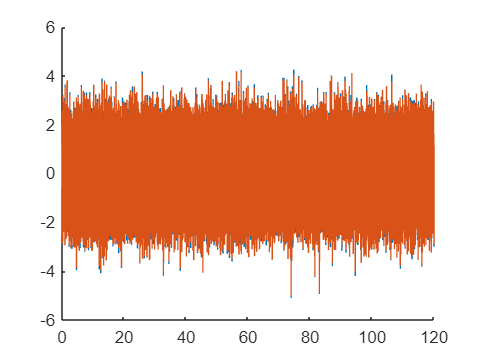

windowsize = 1; %[s]
window = windowsize/stepsize;
figure()
hold on     
plot(u.Time,u.Data)
plot(d.Time,d.Data)




%Tf estimate
figure()
[Sud, F] = tfestimate(d.Data,u.Data,window,[],[],fs);
Sdd = pwelch(d.Data,window)

Sdd =    1.4271e-01
   3.1359e-01
   2.9436e-01
   3.0072e-01
   3.1120e-01
   3.0665e-01
   2.8288e-01
   2.8885e-01
   3.0330e-01
   2.9817e-01


S =  Sud

S =   -1.3680e-01 + 0.0000e+00i
  -9.5314e-02 + 6.0810e-01i
   6.2463e-01 + 8.8225e-01i
   1.0077e+00 + 5.3198e-01i
   1.0382e+00 + 3.4972e-01i
   1.0304e+00 + 2.6302e-01i
   1.0273e+00 + 2.1056e-01i
   1.0218e+00 + 1.7570e-01i
   1.0178e+00 + 1.5135e-01i
   1.0183e+00 + 1.3408e-01i


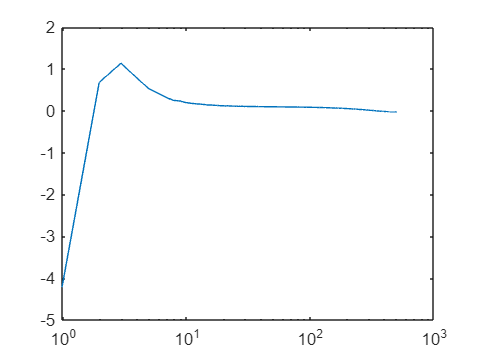

semilogx(F,mag2db(abs(S)))

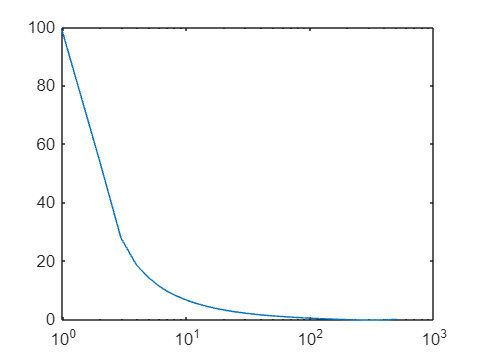

semilogx(F,angle(S)/pi*180)

d) Coherence

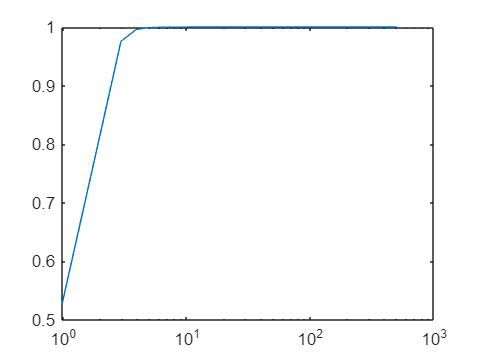

[coherence_ry, F] = mscohere(d.Data,u.Data,window,[],[],fs);
semilogx(F,coherence_ry)

e)

L = 1./S-1

L =   -8.3099e+00 + 0.0000e+00i
  -1.2516e+00 - 1.6050e+00i
  -4.6546e-01 - 7.5501e-01i
  -2.2393e-01 - 4.0969e-01i
  -1.3492e-01 - 2.9142e-01i
  -8.8901e-02 - 2.3256e-01i
  -6.5796e-02 - 1.9149e-01i
  -4.9407e-02 - 1.6346e-01i
  -3.8740e-02 - 1.4295e-01i
  -3.4712e-02 - 1.2710e-01i


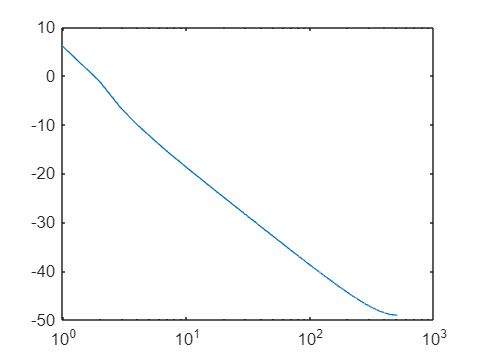

semilogx(F,mag2db(abs(L)))

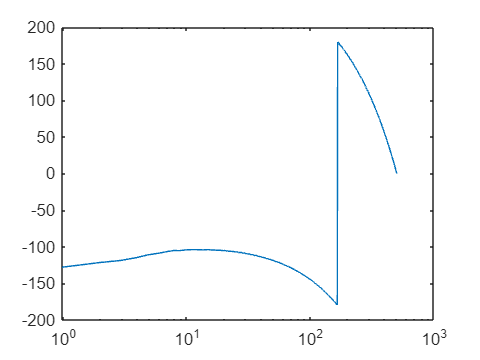

semilogx(F,angle(L)/pi*180)